# Transducer Design

Transducer 1

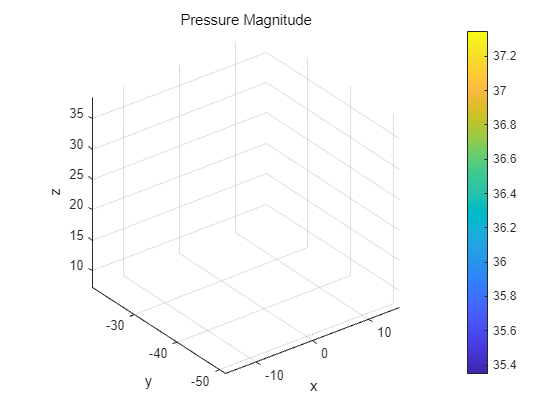

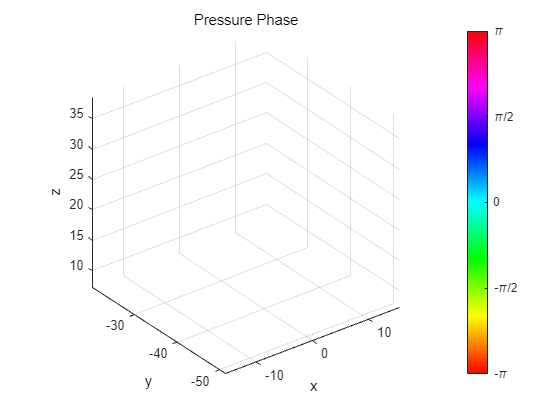

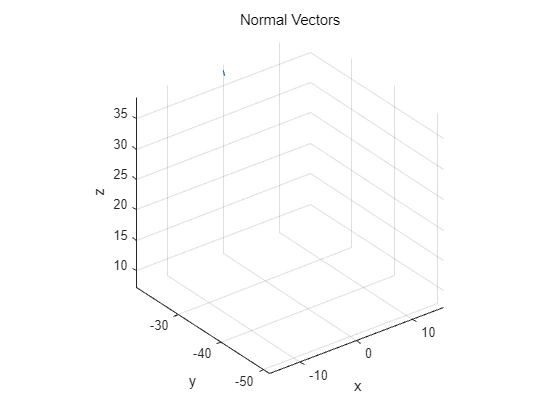

% Define common properties
transducer_info = struct();
transducer_info.Frequency = 4e4;    % 40kHz (operating frequency of transducer)
transducer_info.Pressure = 36.3477;       % Surface outcome pressure [Pa]
transducer_info.Type = 'circle';
transducer_info.Radius = 8e-3;      

transducer_info.medium = 'air';
transducer_info.Phase =0;


% Positions and phases for the transducers (rectangular)
% positions = [];
% for k = 1:8
%     positions(k) = 0.005 + 0.01 * (k-1);
% end
% PFC_PhaseCalculate(target[x,y], array, focal point z(m))
% phases = PFC_PhaseCalculate([0.04, 0.04], [8,8], 0.3)

% Counter for linear indexing into transducer_object
% index = 1;

% Populate the transducer objects
% for i = 1:8
%     for j = 1:8
%         % Update position and phase
%         transducer_info.position = [positions(j), positions(i), 0];
%         transducer_info.Phase = phases(i, j);
%         transducer_object(index) = PFC_Make3DTransducer(transducer_info);
% 
%         % Increment index for next transducer
%         index = index + 1;
%     end
% end

transducer_info.position = [0, -51.447, 8.336];
transducer_info.rotate = [180-65.05, 0, 0];
transducer_object(1) = PFC_Make3DTransducer(transducer_info);

transducer_info.position = [0, -39.45, 25.188];
transducer_info.rotate = [180-43.681, 0, 0];
transducer_object(2) = PFC_Make3DTransducer(transducer_info);

transducer_info.position = [0, -20.254, 37.424];
transducer_info.rotate = [180-20.906, 0, 0];
transducer_object(3) = PFC_Make3DTransducer(transducer_info);




% Draw all transducers in 3D once
PFC_DrawTransducer3D(transducer_object, '-');

## Frequency Domain

input_source.Type = 'frequency';
input_source.reading_list = 1e6; % [Hz]

## Simulation Space

reading_pos_x = 0 : 0.5e-3 : 80e-3;          % Simulation Area
reading_pos_y = 0 : 0.5e-3 : 80e-3;          % Simulation Area
reading_pos_z = 260e-3 : 0.5e-3 : 400e-3;          % Simulation Area

## Run Frequency Domain Simulation

XZ Plane

% xz plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, 0.04, reading_pos_z);

Started at 2024-05-06 00:31:39
Finished at 2024-05-06 00:32:37
Progressed time : 00:00:58


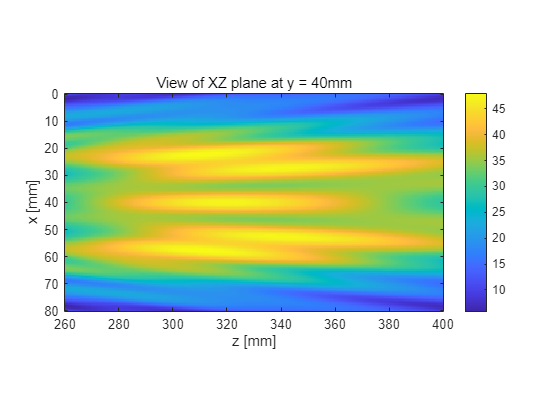


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_z.*1e3, reading_pos_x.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XZ plane at y = 40mm');
colorbar;
xlabel('z [mm]');
ylabel('x [mm]');

M1 = max(Pressure_dxyz_i,[],"all")

M1 = 48.0668

XY Plane

% xy plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, reading_pos_y, 0.3);

Started at 2024-05-06 00:32:38
Finished at 2024-05-06 00:33:11
Progressed time : 00:00:33


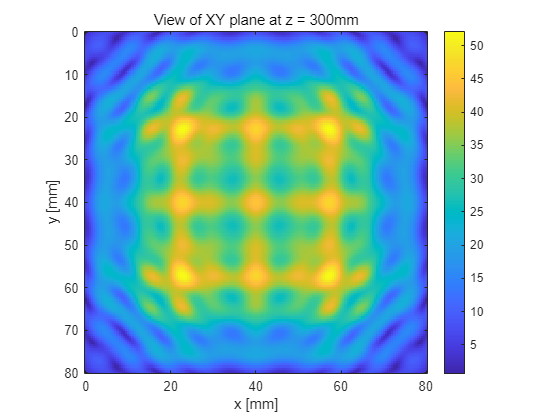


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XY plane at z = 300mm');
colorbar;
xlabel('x [mm]');
ylabel('y [mm]');

M2 = max(Pressure_dxyz_i,[],"all")

M2 = 52.2031